% Parameterize the arm
rho = 0.03; % M, Radius
 
% Construct pose matrices
% Transform from world frame to base curve
g_o = SE2(0, 0, pi/2);

g_o_A = SE2(0, rho/2, 0);
g_o_B = SE2(0, -rho/2, 0);

%% Calculate adjoint matrices
% Adjoints for each muscle, centered on the base curve
ad_o_A = ad_se2(g_o_A);
ad_o_B = ad_se2(g_o_B);

% The inverse: Adjoints centerd on each muscle, mapping from the base
% curve.
ad_A_o = inv(ad_o_A);
ad_B_o = inv(ad_o_B);

l_0 = 0.1; % Default length

% TODO: Maybe this could just be one function? Muscle2D.create_muscles()?
% Construct muscle objects
muscle_A = Muscle2D(l_0, 0, "adjoint_X_o", ad_A_o, "g_0", g_o * g_o_A);
muscle_B = Muscle2D(l_0, 0, "adjoint_X_o", eye, "g_0", g_o * eye(3));
muscle_C = Muscle2D(l_0, 0, "adjoint_X_o", ad_B_o, "g_0", g_o * g_o_B);

muscles = [muscle_A, muscle_B, muscle_C];

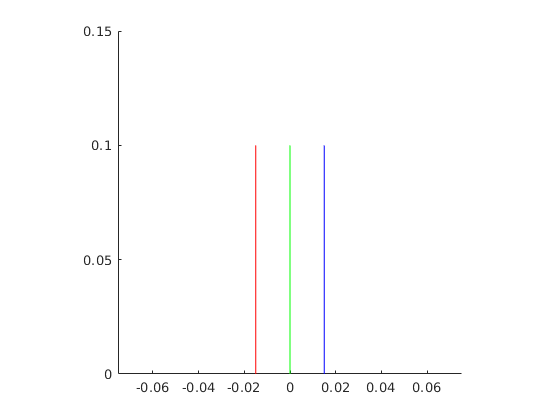

% Initialzie Plotting
muscle_A.color = [1 0 0];
muscle_B.color = [0 1 0];
muscle_C.color = [0 0 1];

% Test plotting
% TODO: Wrap this into its own function?
fig = figure();
ax = axes(fig);

% TODO: Add the color as a property of the muscle object.

for i = 1 : length(muscles)
    muscles(i).plot_muscle(ax);
end

axis equal
border_length_cm = 15;
ylim([0, 1] * border_length_cm / 100);
xlim([-0.5, 0.5] * border_length_cm / 100);

% Calculate N matrix
mat_M = zeros(3);
mat_V = zeros(3, length(muscles));

for i = 1 : length(muscles)
    muscle_i = muscles(i);
    v_i = muscle_i.adjoint_X_o' * [1; 0; 0];
    mat_V(:, i) = v_i;
    mat_M = mat_M + v_i*v_i';
end

mat_N = pinv(mat_M) * mat_V;

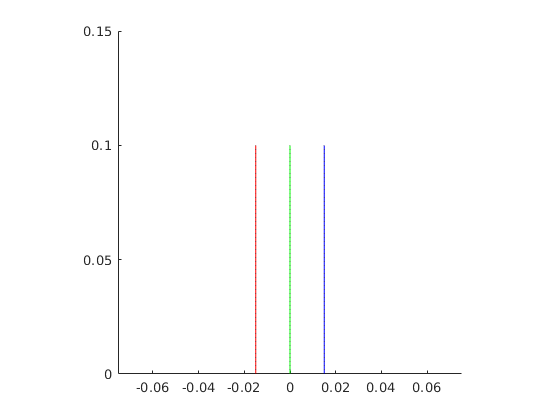

% Construct unstrained muscles
if exist('muscles_unstrained', 'var')
    delete(muscles_unstrained)
end

muscles_unstrained = copy(muscles);
for i = 1 : length(muscles) 
    % "Unstrained" line handles: Copy of actual line handles, but darker
    % Displays muscles if they had the same curvature but the actual
    % intended and unstrained length
    hsv_gains = diag([1, 1, 0.5]);
    muscles_unstrained(i).lh.Color = hsv2rgb(rgb2hsv(muscles(i).lh.Color) * hsv_gains);
    %v_lh_unconstrained(i).Color = 'k';
    muscles_unstrained(i).lh.LineStyle = ':';
    muscles_unstrained(i).lh.Parent = ax;
end

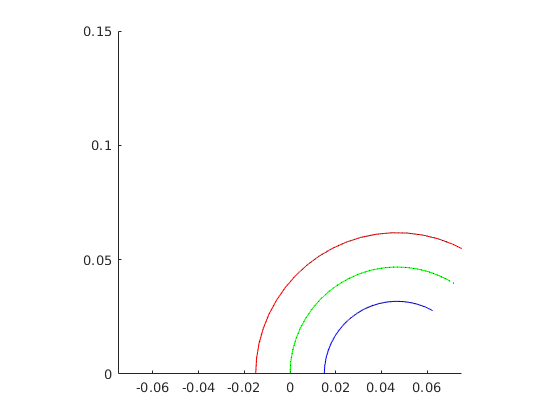

l_A = 0.1275;
l_B = 0.1;
l_C = 0.065;
v_l = [l_A; l_B; l_C];

% Calculate base curve curvature
h_o_tilde = mat_N * v_l;

% Calculate and plot individual muscle lengths
for i = 1 : length(muscles)
    muscles(i).h_tilde = muscles(i).adjoint_X_o * h_o_tilde;
    
    muscles_unstrained(i).h_tilde = muscles(i).h_tilde;
    muscles_unstrained(i).l = v_l(i);
    
    muscles(i).plot_muscle(ax);
    muscles_unstrained(i).plot_muscle(ax);
end


% TODO: Calculate individual strain? Delta_l?